# chapter 1

ut=ux

lambda=-0.9;

## scheme1

NN=[20,40,80,160,320,640];
TT=[1,2,5,10,20];
kk=[1];
scheme=3;

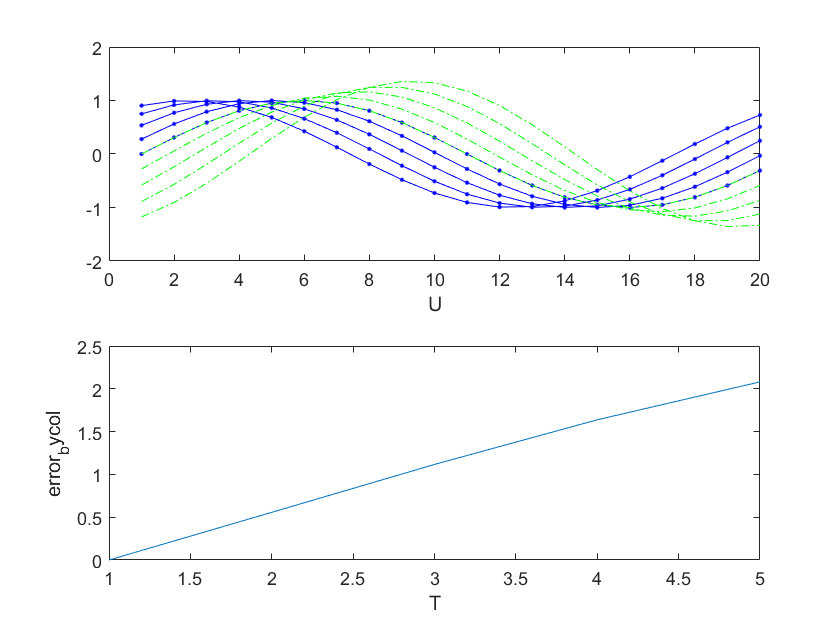

k=1,N=20,T=1,max_error=2.081


L2error=1.4832U_Denergy=0.5V_Denergy=0.9286


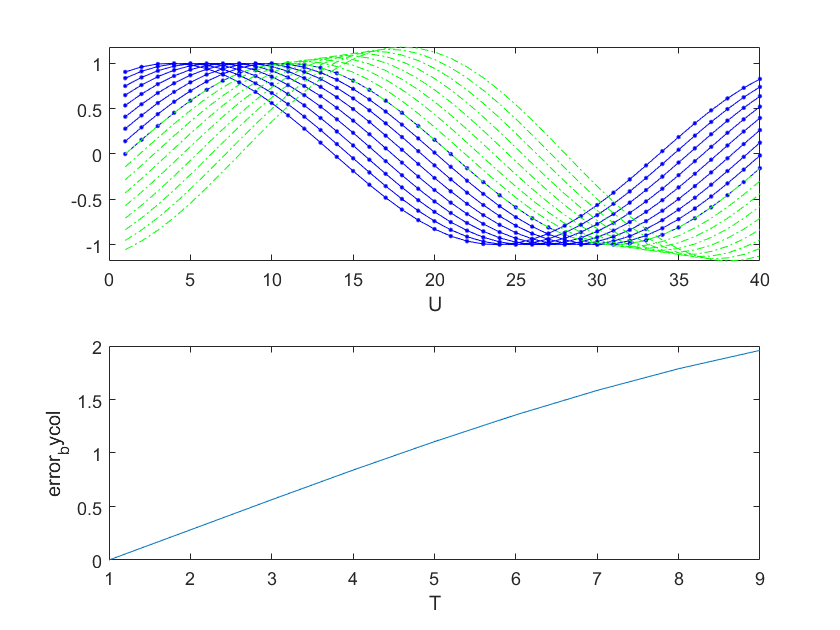

k=1,N=40,T=1,max_error=1.9595


L2error=1.3875U_Denergy=0.5V_Denergy=0.69545


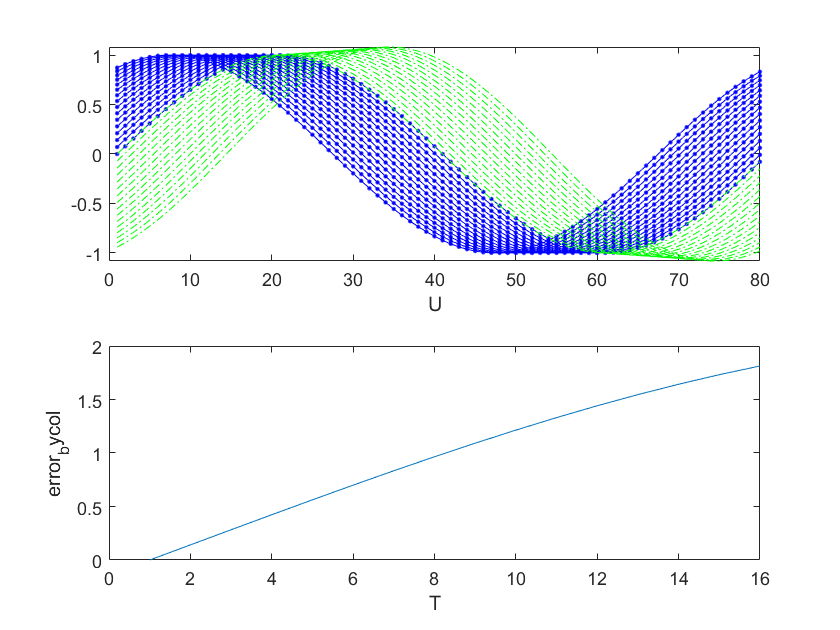

k=1,N=80,T=1,max_error=1.8133


L2error=1.2826U_Denergy=0.5V_Denergy=0.58518


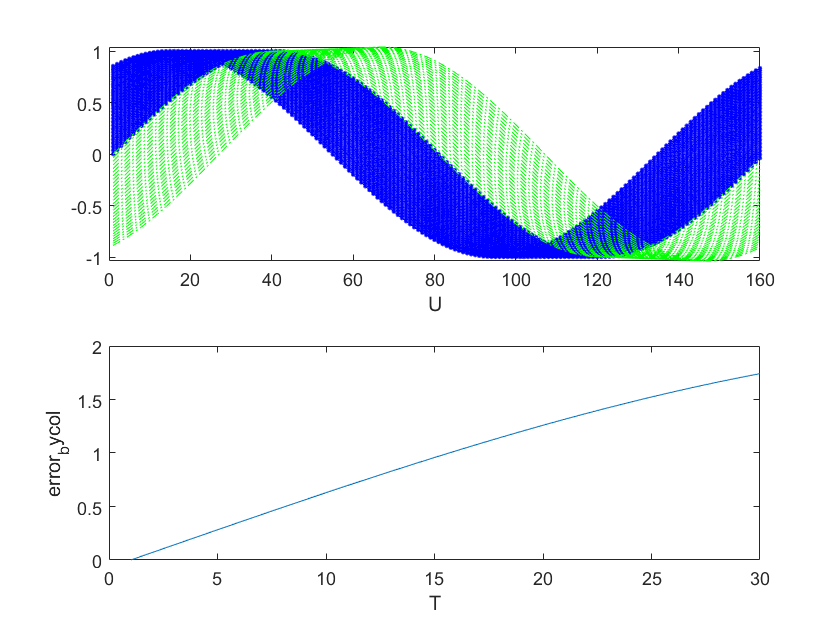

k=1,N=160,T=1,max_error=1.742


L2error=1.2318U_Denergy=0.5V_Denergy=0.53968


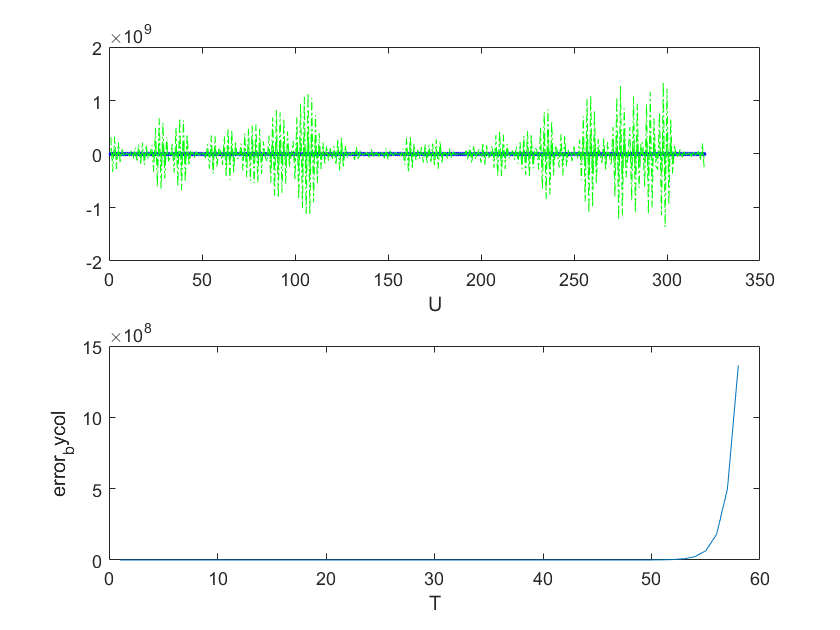

k=1,N=320,T=1,max_error=1363555048.2109


L2error=462355806.566U_Denergy=0.5V_Denergy=2.137728918652704e+17


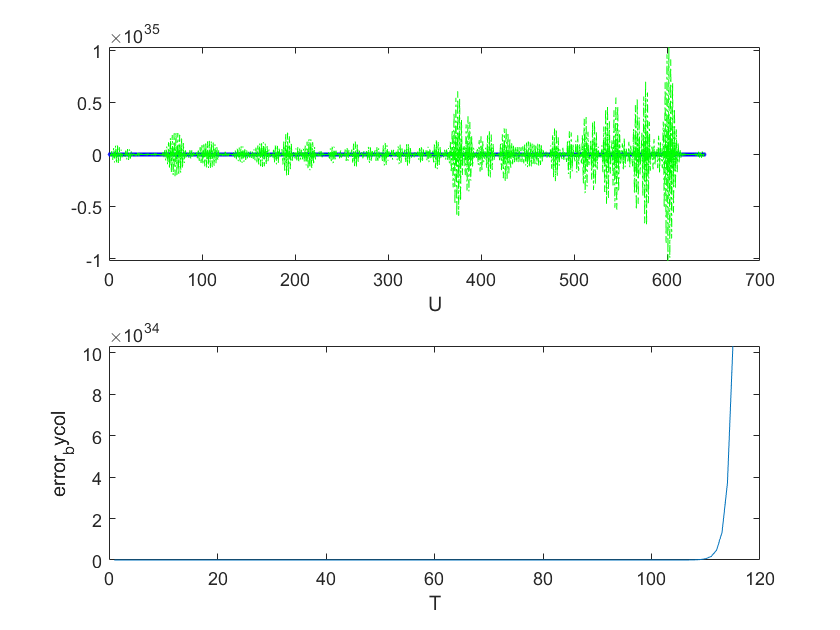

k=1,N=640,T=1,max_error=1.032791801197029e+35


L2error=1.937159429256198e+34U_Denergy=0.5V_Denergy=3.752586654356198e+68


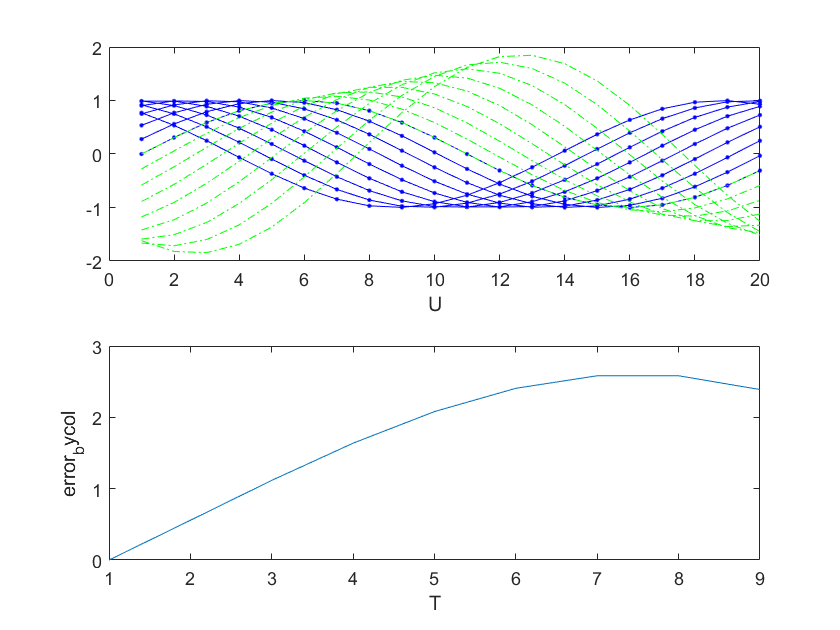

k=1,N=20,T=2,max_error=2.583


L2error=1.7007U_Denergy=0.5V_Denergy=1.7246


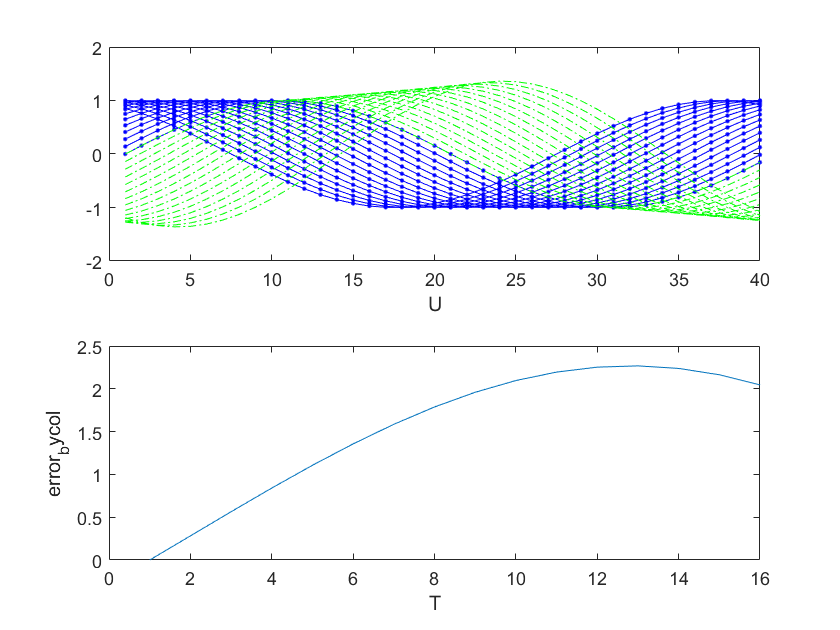

k=1,N=40,T=2,max_error=2.2678


L2error=1.4495U_Denergy=0.5V_Denergy=0.92821


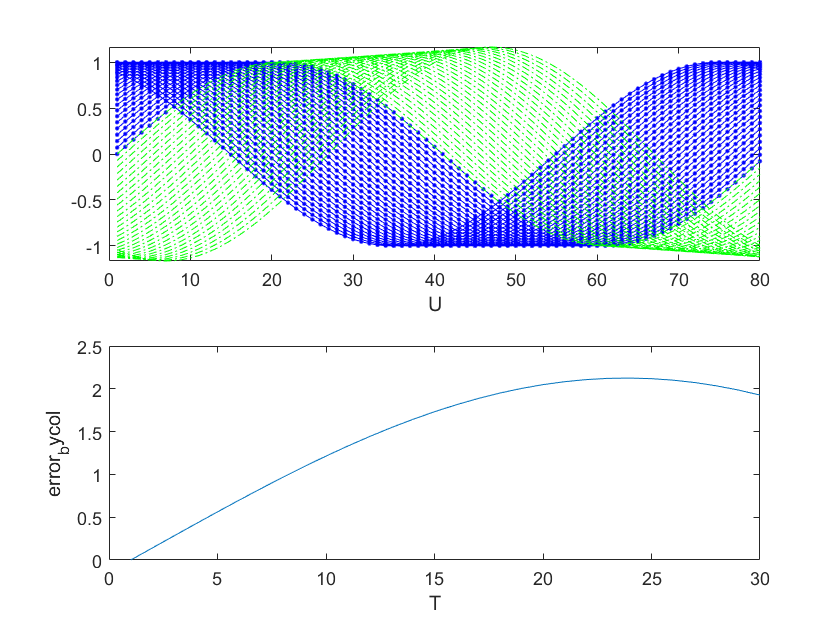

k=1,N=80,T=2,max_error=2.1255


L2error=1.363U_Denergy=0.5V_Denergy=0.67773


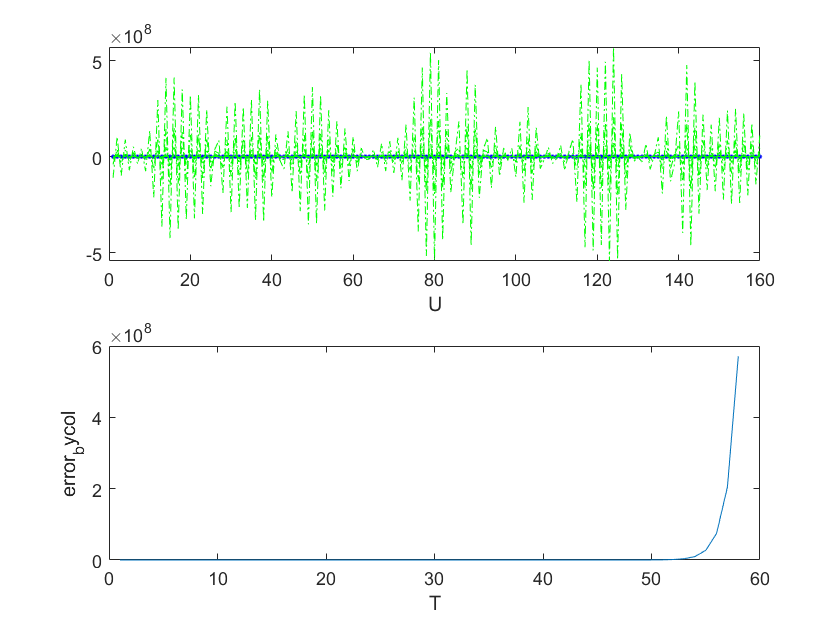

k=1,N=160,T=2,max_error=571121610.4718


L2error=267394460.2022U_Denergy=0.5V_Denergy=7.149979734679959e+16


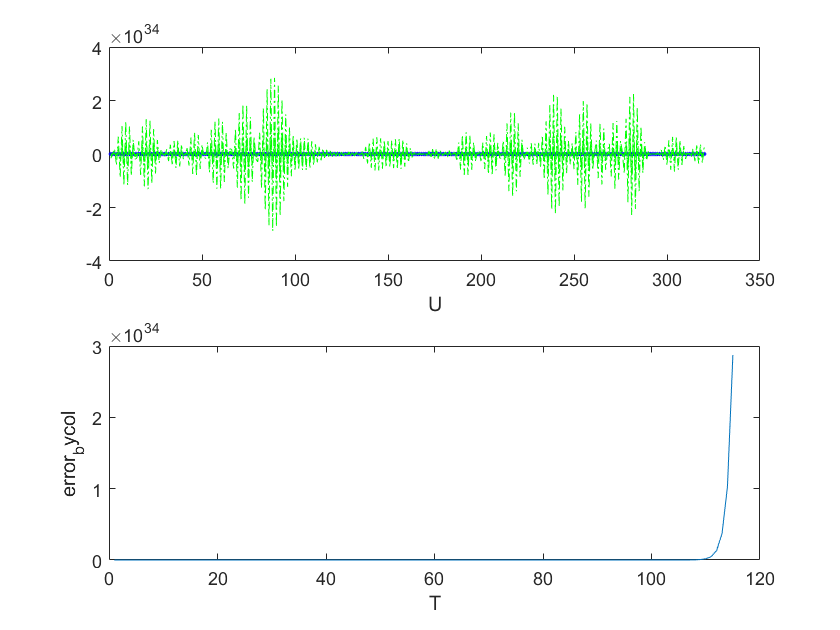

k=1,N=320,T=2,max_error=2.874364462281951e+34


L2error=9.462186167977266e+33U_Denergy=0.5V_Denergy=8.953296707746031e+67


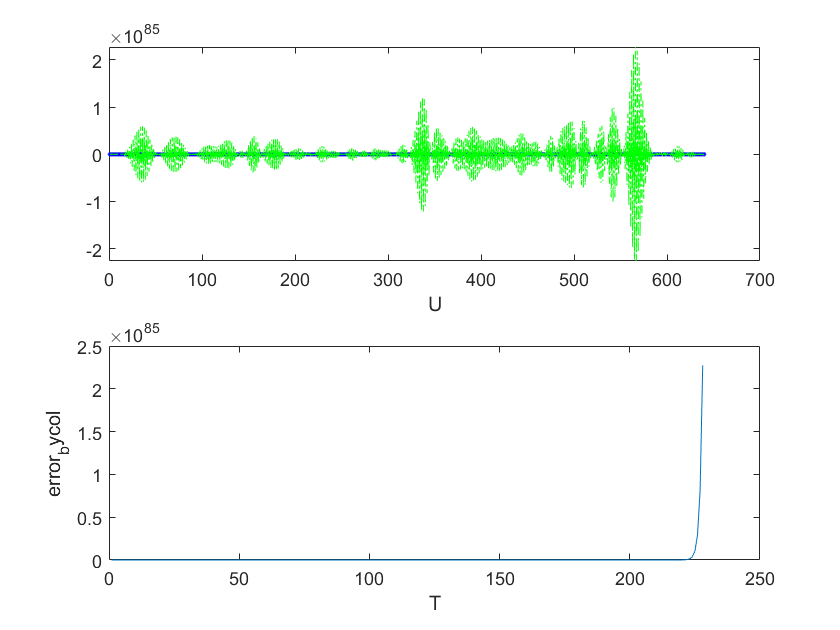

k=1,N=640,T=2,max_error=2.273699083156706e+85


L2error=4.346786653915096e+84U_Denergy=0.5V_Denergy=1.88945542146544e+169


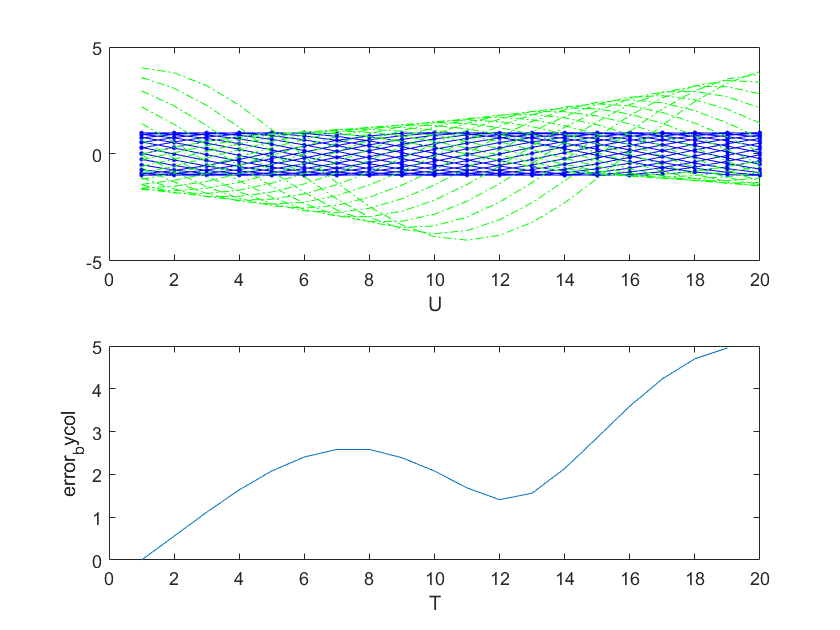

k=1,N=20,T=5,max_error=4.9549


L2error=3.5197U_Denergy=0.5V_Denergy=8.1065


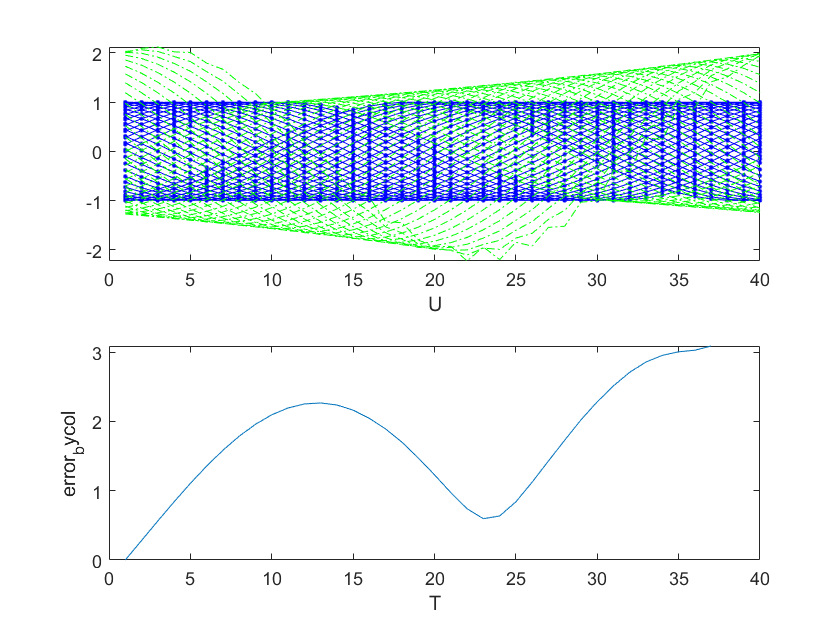

k=1,N=40,T=5,max_error=3.0899


L2error=2.0965U_Denergy=0.5V_Denergy=2.2171


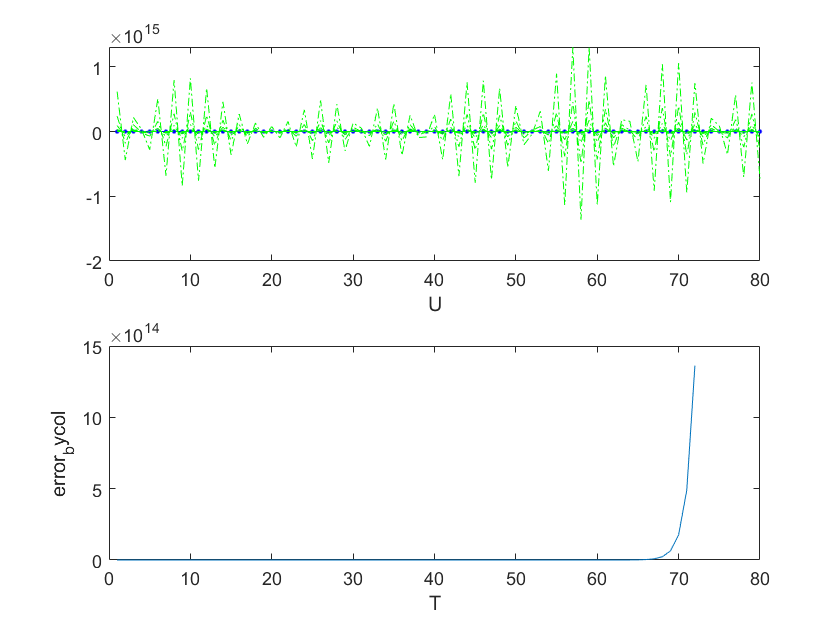

k=1,N=80,T=5,max_error=1362845902932760


L2error=617486327133496.9U_Denergy=0.5V_Denergy=3.812893641968161e+29


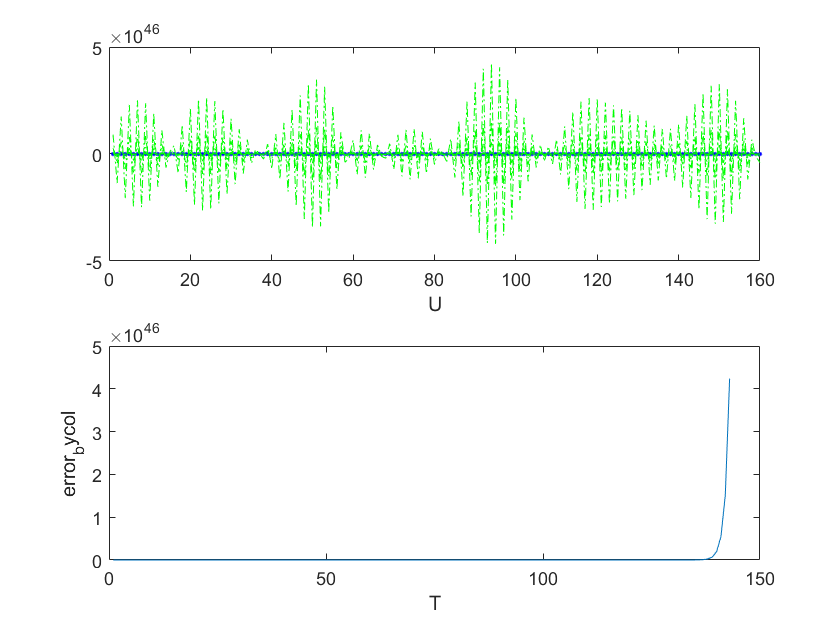

k=1,N=160,T=5,max_error=4.238947336071968e+46


L2error=2.028544921515524e+46U_Denergy=0.5V_Denergy=4.114994498606423e+92


k=1,N=320,T=5,max_error=6.975744711313038e+109


L2error=2.254796993824131e+109U_Denergy=0.5V_Denergy=5.08410948335834e+218


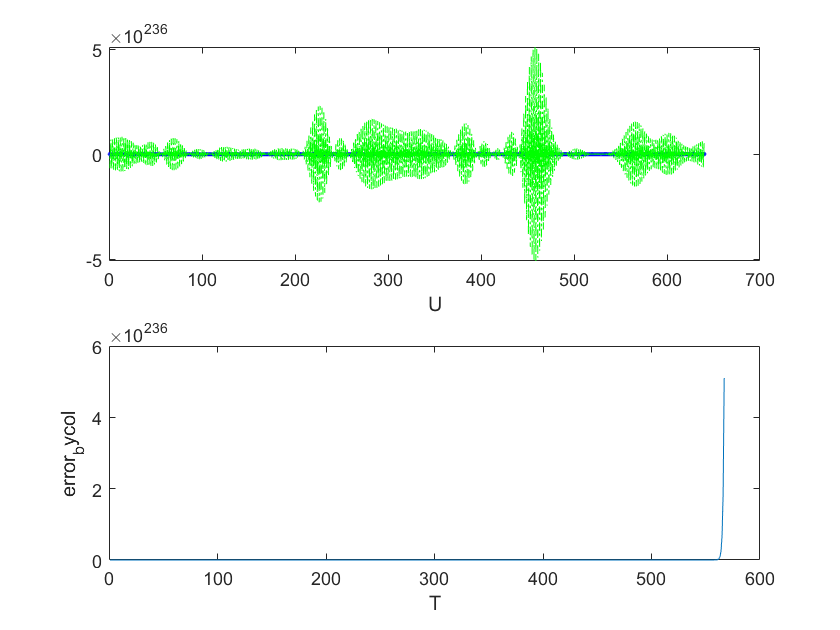

k=1,N=640,T=5,max_error=5.102810635853507e+236


L2error=InfU_Denergy=0.5V_Denergy=Inf


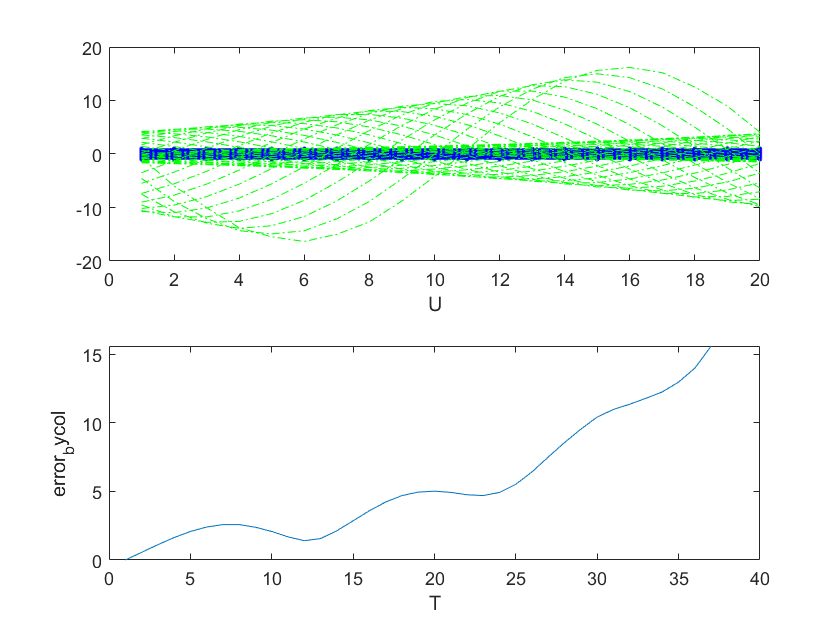

k=1,N=20,T=10,max_error=15.6147


L2error=10.9342U_Denergy=0.5V_Denergy=131.4443


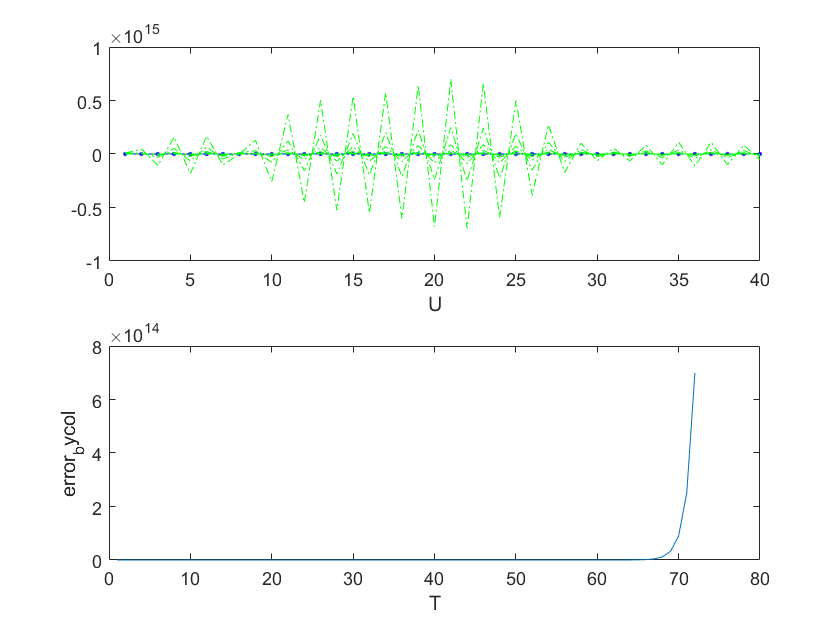

k=1,N=40,T=10,max_error=698946129788550.3


L2error=373858066414501.4U_Denergy=0.5V_Denergy=1.397698538231898e+29


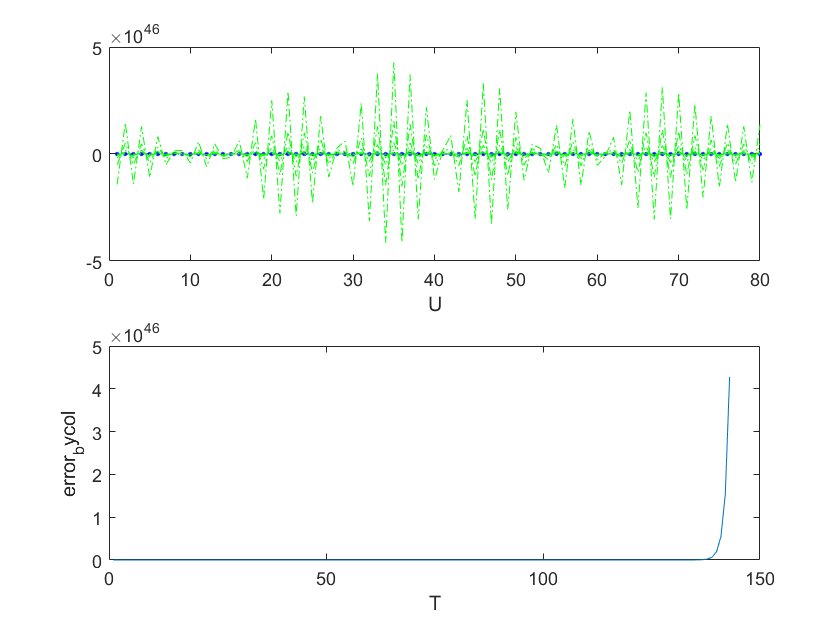

k=1,N=80,T=10,max_error=4.279027317237618e+46


L2error=2.077674011942427e+46U_Denergy=0.5V_Denergy=4.316729299900942e+92


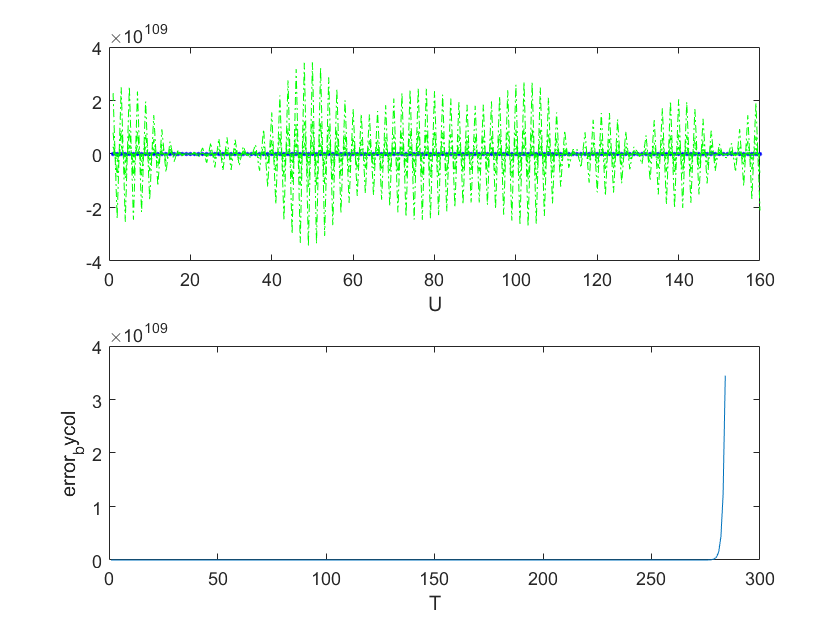

k=1,N=160,T=10,max_error=3.445415863174917e+109


L2error=1.824905345868586e+109U_Denergy=0.5V_Denergy=3.330279521379744e+218


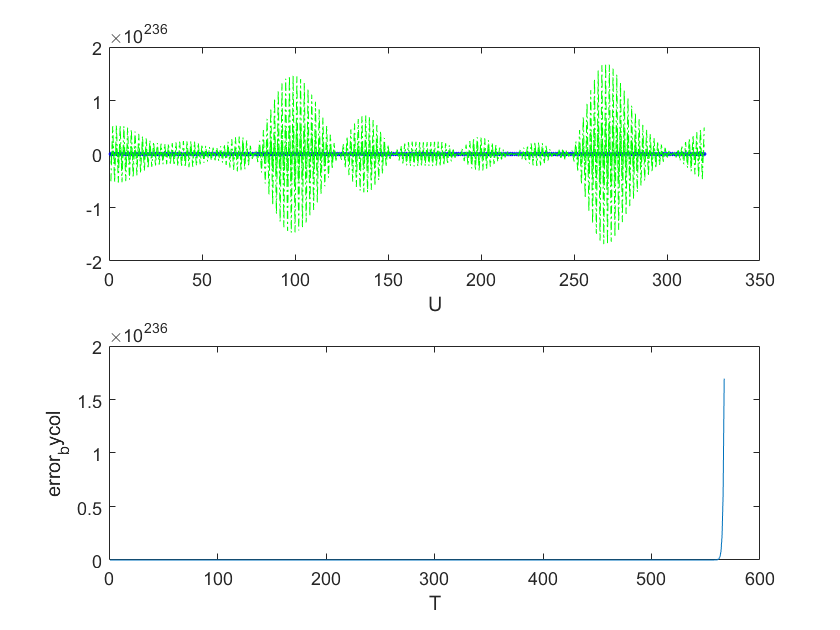

k=1,N=320,T=10,max_error=1.695198734566753e+236


L2error=InfU_Denergy=0.5V_Denergy=Inf


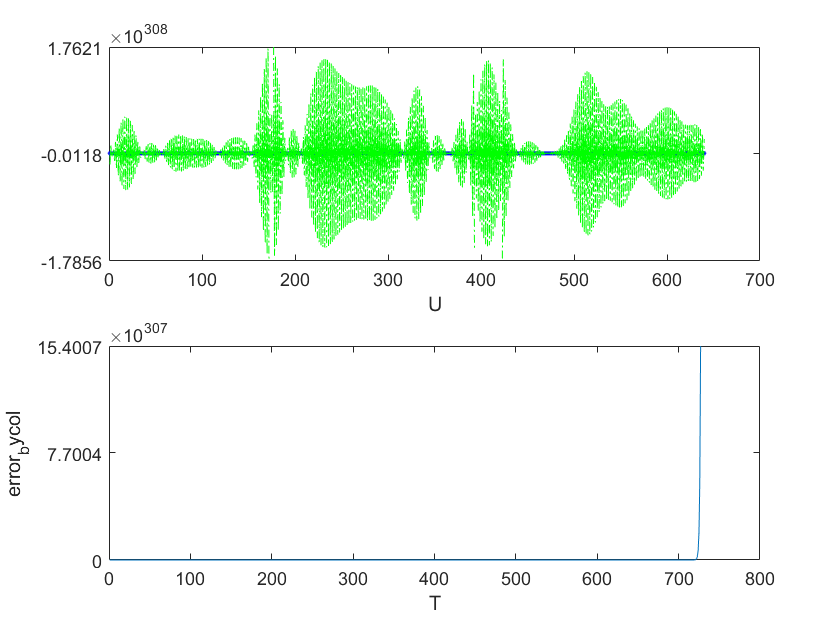

k=1,N=640,T=10,max_error=Inf


L2error=NaNU_Denergy=0.5V_Denergy=NaN


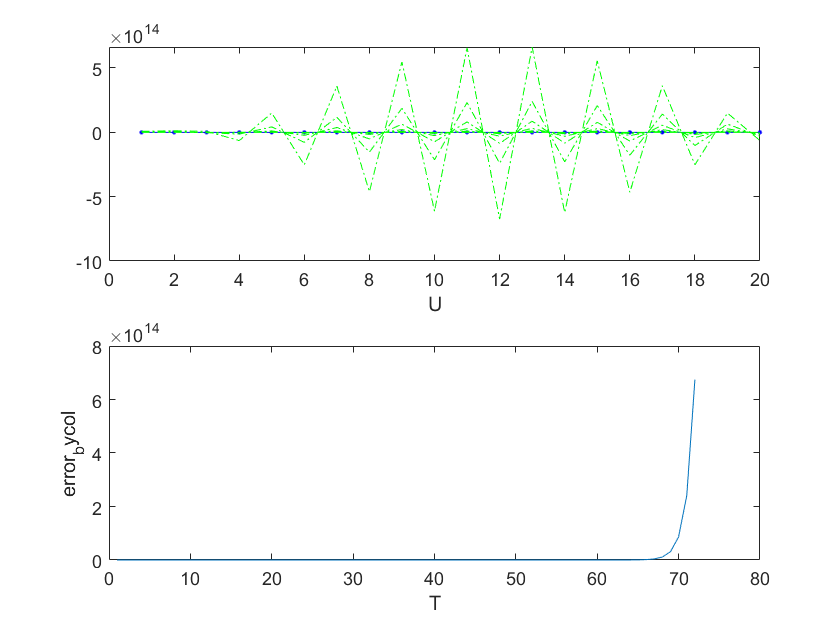

k=1,N=20,T=20,max_error=674070611967115


L2error=422472417804096.9U_Denergy=0.5V_Denergy=1.784829438052394e+29


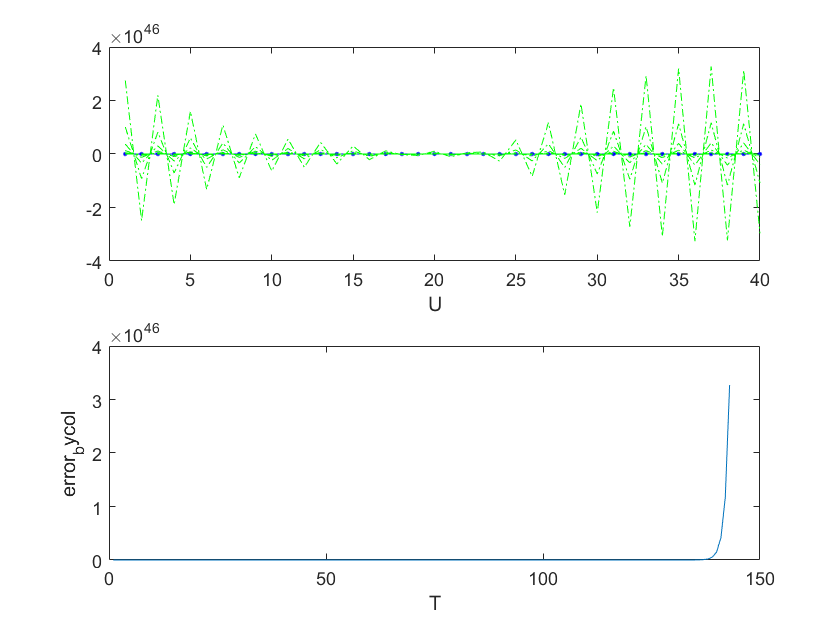

k=1,N=40,T=20,max_error=3.272174835198529e+46


L2error=1.841059373859046e+46U_Denergy=0.5V_Denergy=3.389499618074261e+92


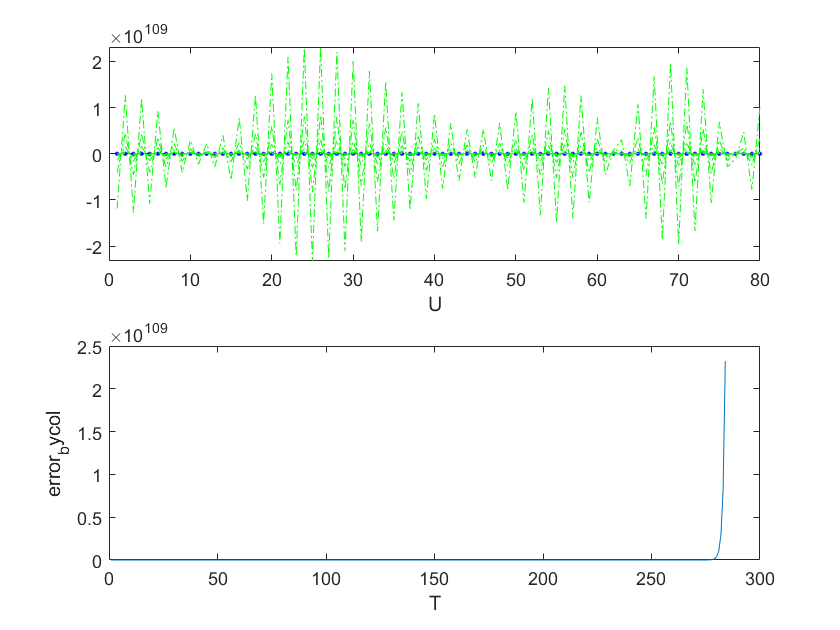

k=1,N=80,T=20,max_error=2.322618505991097e+109


L2error=1.306970520397035e+109U_Denergy=0.5V_Denergy=1.708171941186898e+218


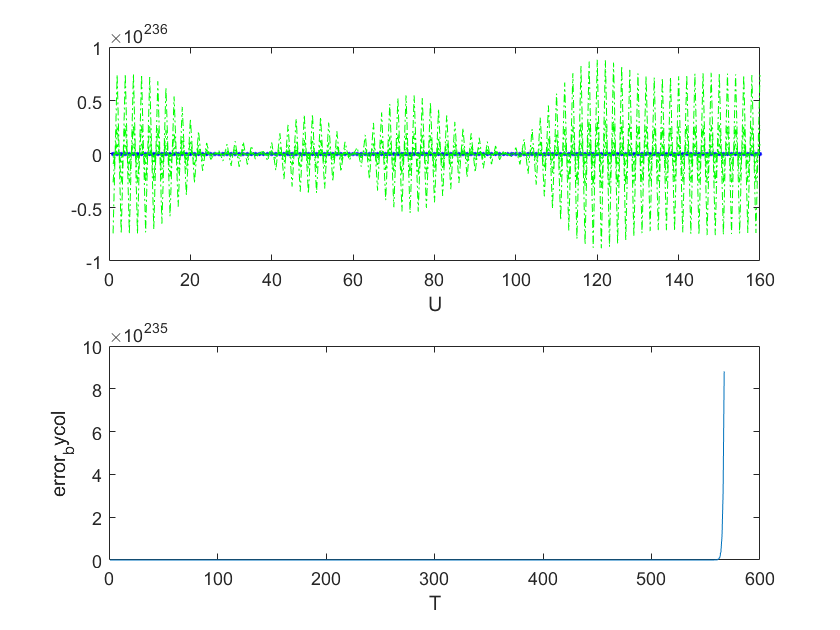

k=1,N=160,T=20,max_error=8.813593836257474e+235


L2error=InfU_Denergy=0.5V_Denergy=Inf


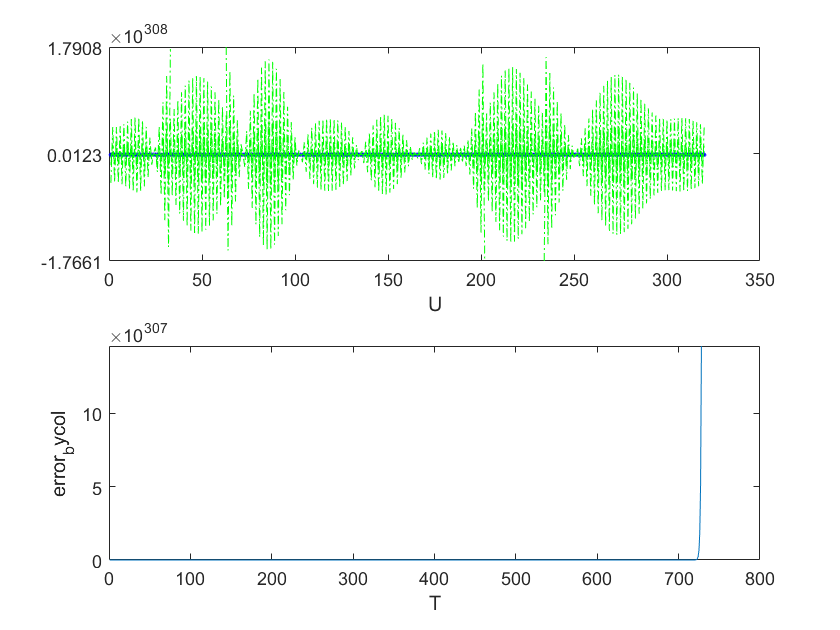

k=1,N=320,T=20,max_error=Inf


L2error=NaNU_Denergy=0.5V_Denergy=NaN


k=1,N=640,T=20,max_error=Inf


L2error=NaNU_Denergy=0.5V_Denergy=NaN


for ind_k=1:length(kk)
    k=kk(ind_k);
    for ind_T=1:length(TT)
        T=TT(ind_T);
        for ind_N=1:length(NN)
            N=NN(ind_N);
            [V,U]=IVP_1D_fd(lambda,N,T,k,scheme); 
            [error_bycol, error_matrix, max_error_bycol] = error_analysis_onebyone(U,V);
            disp(['k=',num2str(k),',N=',num2str(N),',T=',num2str(T),',max_error=',num2str(max_error_bycol)])
            L2error=error_analysis_L2error(U,V);
            [U_Denergy,V_Denergy]=error_analysis_Denergy(U,V);
            disp(['L2error=',num2str(L2error),'U_Denergy=',num2str(U_Denergy),'V_Denergy=',num2str(V_Denergy)])
        end
    end
end